Boundary Value Problems!

Shooting Method

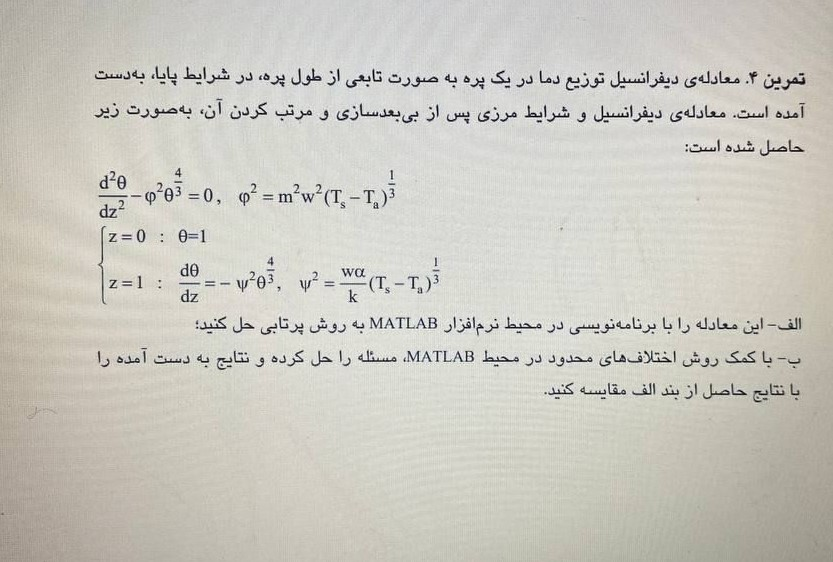

    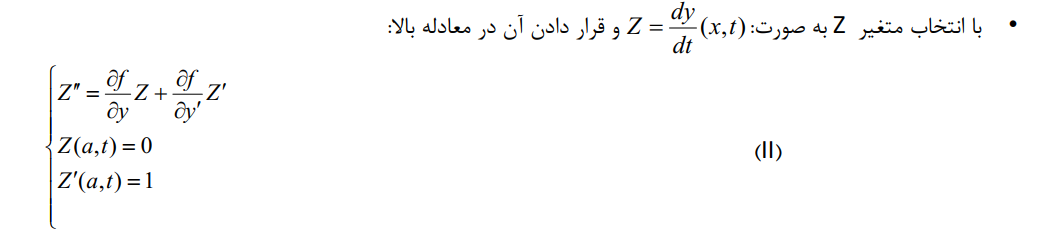

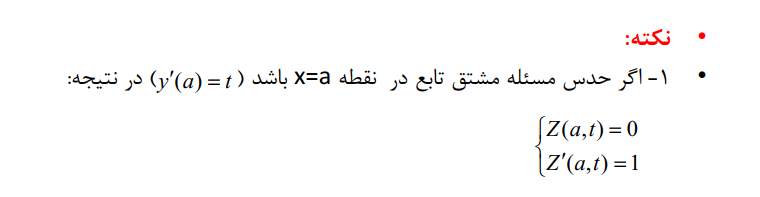

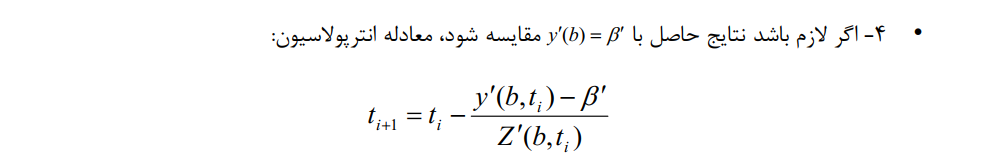

We need to solve this Problem:

    theta -- >> y         :::::: Change of Variable Names for simplicity!

    z       -- >> x


$${y^{\prime } }^{\prime } =m^2 w^2 {\left(T_s -T_a \right)}^{\frac{1}{3}} \ldotp y^{\frac{4}{3}} \;\;\;;$$


for $y\left(a\right)\;=1\;\;\;\;;\;\;\;\;\;\;\;\;\;\;y^{\prime } \left(1\right)=w\frac{\alpha }{k}{\left(T_s -T_a \right)}^{\frac{1}{3}} \ldotp y^{\frac{4}{3}} \;;\;$


$${y^{\prime } }^{\prime } \;=f\left(x,y\right)\;=m^2 w^2 {\left(T_s -T_a \right)}^{\frac{1}{3}} \;\;y^{\frac{4}{3}} \;;\;\;=\Rightarrow \;\;\mathrm{if}\;\;\;\;y^{\prime } =w\;;\;\;w^{\prime } =f\;--\to \;$$


$\left\lbrace \begin{array}{ll}
y^{\prime } =W & ;\;\;\;y\left(0\right)=1;\\
W^{\prime } =m^2 w^2 {\left(T_s -T_a \right)}^{\frac{1}{3}} y^{\frac{4}{3}}  & ;\;\;\;\;\;y^{\prime } \left(1,\mathrm{t1}\right)=\mathrm{t1}\;\;\;--\mathrm{guess}
\end{array}\right.$   ;      $\left\lbrace \begin{array}{ll}
Z^{\prime } =u; & :\;\;\;Z\left(0,\mathrm{t1}\right)=0\;;\\
u^{\prime } =\frac{4}{3}m^2 w^2 {\left(T_s -T_a \right)}^{\frac{1}{3}} y^{\frac{1}{3}} Z; & ;\;\;\;\;Z^{\prime } \left(1,\mathrm{t1}\right)=1;
\end{array}\right.$

To make it simpler in form we can use:


$$\begin{array}{l}
y-\to \;\;\mathrm{y1}\\
W-\to \mathrm{y2}\\
Z-\to \;\mathrm{y3}\\
u-\to \;\;\mathrm{y4}\;
\end{array}$$


and then we have:


$$\begin{array}{l}
{\mathrm{y1}}^{\prime } =\mathrm{y2};\\
{\mathrm{y2}}^{\prime } =\mathrm{MULTING}*{\mathrm{y1}}^{\frac{4}{3}} ;\\
{\mathrm{y3}}^{\prime } =\mathrm{y4};\\
{\mathrm{y4}}^{\prime } =\frac{4}{3}*\mathrm{MULTING}*{\mathrm{y1}}^{\frac{1}{3}} *\mathrm{y3}
\end{array}$$


clear; clc; close all;

T = zeros(20,1);

m = 1;   w = 2; Ts  =210; Ta = 180; alpha = 0.2; k = 1; 

global MULTING

MULTING = m^2 * w^2 * (Ts - Ta)^(1/3);

a = 0;
b =1;


T(1) = b*randi(1);  % Guess
tspan = [0.1  1];

opts = odeset('RelTol',1e-2,'AbsTol',1e-4);


for i=1:length(T)
    ic = [1 T(i) 1 1];
    [t,Y] = ode45(@(t,y) ODE_W(t,y), tspan, ic, opts);
 %%% Update t
     y_prime_sol = Y(end,2);
     Z_prime_sol = Y(end,4);
     beta_guess  = Y(end,1);
     if (i>2) % we are comparing y'(b) = Beta' --> so we choose the interpolation formula of:
        T(i+1) = T(i) - (y_prime_sol-beta_guess )/Z_prime_sol; % Interpolation
     else
        T(i+1) = randi(1); % Second Guess
     end

end

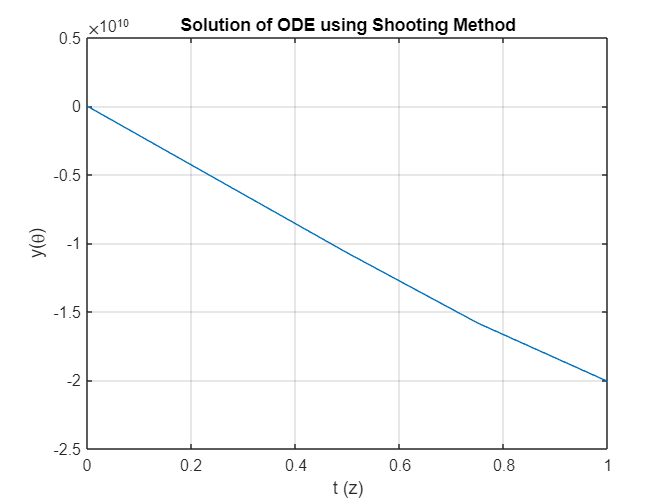

t = linspace(0,1,length(Y(:,1)));
figure(1)
plot(t,Y(:,1));
grid on
ylabel("y(\theta)")
xlabel("t (z)")
title("Solution of ODE using Shooting Method")

function  dy = ODE_W(t,y)
dy = zeros(4,1);

global MULTING
dy(1)  =  y(2);
dy(2)  = MULTING*(y(1).^4/3);
dy(3)  =  y(4);
dy(4)  =  4/3*MULTING*(y(1).^1/3)*y(3) ;
 
end

